Implement the pattern search method using one of the fixed direction sets Dn discussed

on the lecture (e.g. the "coordinate direction set" or the "simplex set"). Use the sufficient

decrease function ρ(t) = 0. Set some suitable hyperparameter values for γtol, θ and φ at the

beginning of function.

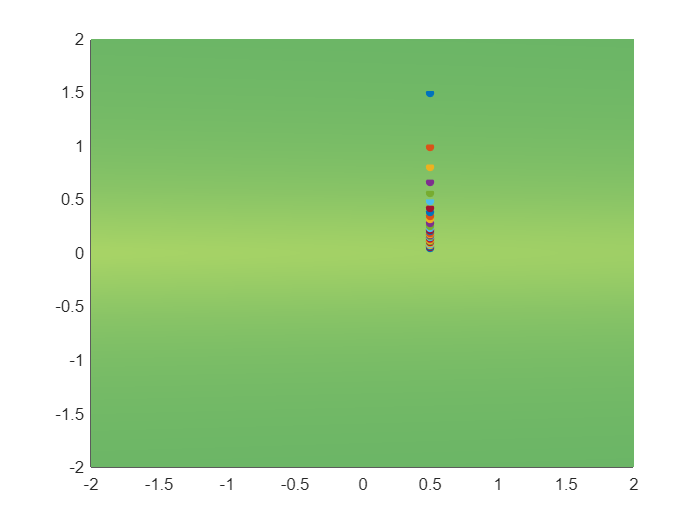

% convex paraboloid(s)
% recommended region: [-2,2]x[-2,2]
a = 0.01;
f=@(x) a.*x(1).^2+x(2).^2;

gtol = 1e-12;
theta = 0.5;
Dk = [1 0 -1 0; 0 1 0 -1];
x0 = [0.5; 1.5];
g0 = 1;
iter = 100;
rho = @(t) 3 * t^(3/2); 
phi = 1.5;
res = 256;

x = pattern_search(f, gtol, theta, Dk, x0, g0, iter, rho, phi);

% plotting
X = linspace(-2,2,res);
Y = linspace(-2,2,res);
[X_m, Y_m] = meshgrid(X,Y);
Z = zeros(res, res);
for i = 1:res
    for j = 1:res
        Z(i,j) = f([X_m(i,j), Y_m(i,j)]);
    end
end
figure; hold on;
surfl(X_m, Y_m, Z);
for i = 1:size(x, 2)
    px = x(1,i);
    py = x(2,i);
    pz = f([px,py]);
    plot3(px,py,pz, '.', MarkerSize=15, MarkerFaceColor=[1,0,0]);
end
colormap("summer");
shading interp;
hold off;

function xs = pattern_search(f,gtol,theta,Dk,x0,g0,iter,rho,phi)
    gamma = g0;
    xk = x0;
    xs = [xk];
    for k=1:iter
        if(gamma<=gtol)
            break;
        end

        flag = 0;
        for i=1:size(Dk,2)
            pk = Dk(:,i);
            fx = f(xk + gamma * pk);
            thresh = f(xk) - rho(gamma);
            if(fx < thresh)
                xk = xk + gamma * pk;
                gamma = phi * gamma;
                flag = 1;
                xs = [xs xk];
                break;
            end
        end

        if(flag==0) 
            gamma = theta * gamma;
        end
    end
end